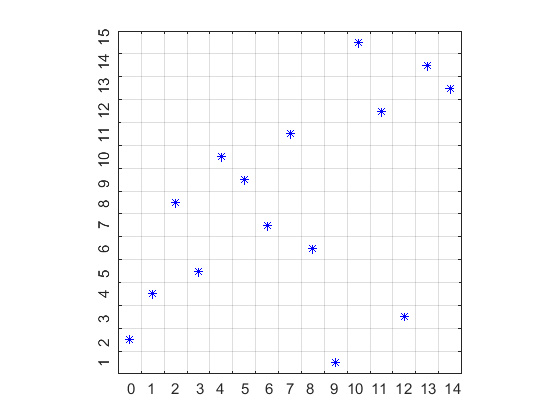

clear all;
v = [2 4 8 5 10 9 7 11 6 1 15 12 3 14 13];
n = 15; % 벡터길이  
plot(1:n, v, 'Linestyle', 'none', 'Marker','*', ...
    'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b')
axis equal
grid on
set(gca, ... % set : 그래픽 객체 속성 설정, gca : 좌표축 또는 차트 반환
    'XTick', 0.5:(n+0.5), ... % x축 눈금 설정
    'YTick', 0.5:(n+0.5), ... % y축 눈금 설정  
    'XLim', [0.5 (n+0.5)], ... % x축 길이제한 설정 
    'YLim', [0.5 (n+0.5)], ... % y축 길이제한 설정
    'XTickLabel', '', ...
    'YTickLabel', '', ...
    'GridLineStyle','-')

xlabel('  0   1    2    3   4    5    6   7   8    9  10  11  12  13  14')
ylabel('  1   2    3    4   5    6    7   8   9   10  11  12  13  14  15')

## Frequency Hopping

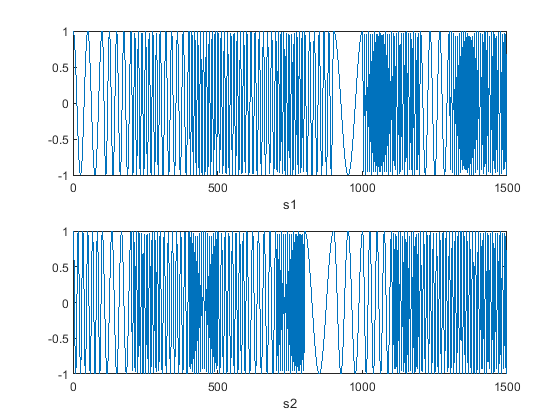

% v = [2 4 8 5 10 9 7 11 6 1 15 12 3 14 13];
dt = 0.01;     %[μs]
t = 0:dt:1-dt; %[μs]
s1 = [];
f0 = 1;        %[MHz]

for i = 1:15
    s1 = [s1 cos(2*pi*f0*v(i)*t)];
end
subplot(211),plot(s1)
xlabel('s1')

%-----------------------------------------------------------

v_rand = randperm(15); % random permutation
dt = 0.01;      %[μs]
t = 0:dt:1-dt;  %[μs]
s2 = [];
f0 = 1;         %[MHz]
for i = 1:15
    s2 = [s2 cos(2*pi*f0*v_rand(i)*t)];
end
subplot(212),plot(s2)
xlabel('s2')

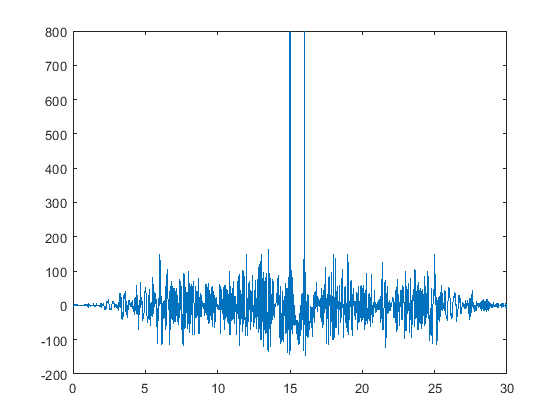


%------------------------------------------------------------

N=length(s1); % length(s1) = length(s2)
r1 = [ zeros(1,N), s1, zeros(1,N) ];
r2 = [ zeros(1,N+100), s2, zeros(1,N-100) ];
r = r1 + r2; 

 ct1 = length(r)-N; % 4500 - 1500
    for a = 0:ct1   % a = 0 : 3000
        c(a+1) = r(a+1:a+N)*(s1+s2)';
    end

subplot(111),plot((0:length(c)-1)*dt,c)

    
y1 = s1*s2'

y1 = -2.8477e-14

y2 = s1*s1'

y2 = 750.0000

y3 = s2*s2'

y3 = 750.0000

%----------------------- 분해능 확인 -----------------------
[m,k1] = max(c);         % 첫번째 범위 max
c2 = c(length(t) : end); % 중간부터 끝까지 ...
[n,k2] = max(c2);        % 두번째 범위 max   
time_diff = ((length(t)*2+k2-k1))*dt; % [μs], dt = 0.01
D_out = (time_diff/2)*3*10^8*10^-6;   % [m/μs] (micro second로 단위변환)
%------------------------ output ---------------------------
time_diff   % 시간차

time_diff = 1.0100

D_out       % 거리

D_out = 151.5000